% clear

initialDirectory = pwd;
basePath = 'F:\Users\Mika\Documents\Studium_HKA\Semester1\ProjektarbeitEkg\Daten\ptb-xl-a-large-publicly-available-electrocardiography-dataset-1.0.3\records500\00000\';
cd(basePath);
subPath = '00001_hr';
% filePath = strcat(basePath,subPath);
fileName = subPath;
%wfdb2mat(filePath,(1:13)');
%[tm,signal,Fs,siginfo]=rdmat('00001_lrm');
[signal,Fs,tm]=rdsamp(fileName);

ecg = signal;

% % visualize raw input signal
% figure; 
% ax1 = subplot(1,4,1);
% plot(ecg(:,1), 'LineWidth', 2); 
% title('Unfiltered ECG Signal Lead I');
% xlabel('time in ms'); ylabel('voltage in mV');
% hold all; 


%% filtering of the 12-lead ECG

% Remove baseline wander
% usage: [filtered_signal,baseline]=ECG_Baseline_Removal(signal,samplerate,window_length,overlap)
[ecg_filtered_baseline,~] = ECG_Baseline_Removal(ecg,Fs,1,0.5);

% % visualizing waveforms
% ax2 = subplot(1,4,2);
% plot(ecg_filtered_baseline(:,1), 'LineWidth', 2); 
% title('Baseline Removal');
% xlabel('time in ms'); ylabel('voltage in mV');
% linkaxes([ax1, ax2],'xy')

% filter noise frequencies
% frequencies are already optimized for ECG signals (literature values):
% Lowpass: 120 Hz, Highpass: 0.3 Hz, Bandstop (49-51 Hz)
[ecg_filtered_frq] = ECG_High_Low_Filter(ecg,Fs,1,40);
ecg_filtered_frq=Notch_Filter(ecg_filtered_frq,Fs,50,1);

% % visualizing waveforms
% ax3 = subplot(1,4,3);
% plot(ecg_filtered_frq(:,1), 'LineWidth', 2); 
% title('Highpass, Lowpass, Bandstop');
% xlabel('time in ms'); ylabel('voltage in mV');
% linkaxes([ax1, ax2, ax3],'xy')

% isoline correction
% usage: [filteredsignal,offset,frequency_matrix,bins_matrix]=Isoline_Correction(signal,varargin)

[ecg_filtered_isoline,offset,~,~]=Isoline_Correction(ecg_filtered_frq);

% ax4 = subplot(1,4,4);
% plot(ecg_filtered_isoline(:,1), 'LineWidth', 2); 
% title('Isoline Correction');
% xlabel('time in ms'); ylabel('voltage in mV');
% linkaxes([ax1, ax2, ax3, ax4],'xy')


%% Feature calculation
% produce FPT Table
% usage: [FPT_MultiChannel,FPT_Cell]=Process_ECG_Multi(signal,samplerate,varargin)
[FPT_MultiChannel,FPT_Cell]=Annotate_ECG_Multi(ecg_filtered_isoline,Fs);

Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Detecting R Peaks...
Done
Syncing beats...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Detecting T Waves...
Done
Detecting P Waves...
Done
Syncing beats...
Done


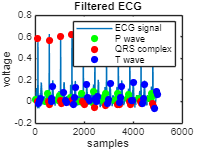


% extract FPTs for Channel 1 (Lead I):
FPT_LeadI = FPT_Cell{3,1};

Pwave_samples = reshape(FPT_LeadI(:,1:3), [1,size(FPT_LeadI(:,1:3),1)*size(FPT_LeadI(:,1:3),2)]);
QRS_samples = reshape([FPT_LeadI(:,4),FPT_LeadI(:,6), FPT_LeadI(:,8)] , [1,size(FPT_LeadI(:,1:3),1)*size(FPT_LeadI(:,1:3),2)]);
Twave_samples = reshape(FPT_LeadI(:,10:12), [1,size(FPT_LeadI(:,10:12),1)*size(FPT_LeadI(:,10:12),2)]);

% visualize fiducial points
figure; 
plot(ecg_filtered_isoline(:,1));
% plot(ecg_filtered_isoline(:,1));
hold on; 
scatter(Pwave_samples, ecg_filtered_isoline(Pwave_samples,1), 'g', 'filled');
scatter(QRS_samples, ecg_filtered_isoline(QRS_samples,1), 'r', 'filled');
scatter(Twave_samples, ecg_filtered_isoline(Twave_samples,1), 'b', 'filled');
title('Filtered ECG');
xlabel('samples'); ylabel('voltage');
legend({'ECG signal', 'P wave', 'QRS complex', 'T wave'});


% %% Calculate timing and amplitude features from FPT table
% [Amplitude_feature_12leads] = ExtractAmplitudeFeaturesFromFPT(FPT_Cell, ecg_filtered_isoline);
% [Timing_feature_12leads, Timing_feature_sync] = ExtractIntervalFeaturesFromFPT(FPT_Cell, FPT_MultiChannel);
% 
% % visualize R amplitude for lead II and V1
% figure; hold all; 
% nbrBeats = size(Amplitude_feature_12leads, 2);
% scatter(1:1:nbrBeats, Amplitude_feature_12leads(2,:,1), 'r+'); % lead II (entry 2), all beats, R peak amplitude (entry 3)
% scatter(1:1:nbrBeats, Amplitude_feature_12leads(7,:,1), 'ro'); % lead V1 (entry 7), all beats, R peak amplitude (entry 3)
% xlabel('Beat ID')
% ylabel('R peak amplitude in mV') 
% legend({'R amplitude in II', 'R amplitude in V1'})

cd(initialDirectory);